# Recommended MATLAB Commands for McCabe-Thiele Calculator Project

Sharif University of Technology, spring 2024, Industrial Unit Operations in Chemical Engineering

Teaching Assistant: Pouria Motahhari 

## 1) Curve Fitting of Equillibrium Data

    Since TA does not modify or change anything in your written code, you have to take the equillibrium data as an input to your code. This can be done in any way of your liking. But it is recommended to use these commands to import your data as a text file.

disp("Please upload the equilibrium file");

Please upload the equilibrium file


[file,path]=uigetfile('.txt');


    Where 'file' and 'path' values are in Char format that need to be converted to String format to import the data from the computer.

EqTxtFilePath= convertCharsToStrings([path file]);

VLE=importdata(EqTxtFilePath); %Eq data in a normal Array
xe=VLE(:,1); %x_equilibrium
ye=VLE(:,2); %y_equilibrium


    After extracting and importing an appropriate equillibrium data from NIST (National Institute of Standards and Technology) Database on Aspen Plus to your code, You'll need to fit the data to a proper model. It can be done on either in the final code or on Curve Fitter app on MATLAB itself. (note that in order to use Curve Fitter app you'll need to write further instructions in your report).

    To fit the extracted equillibrium data directly on your code this fit command will be used:

[eq_curve,gof]=fit(xe,ye,'poly5');


    Only for polynomial models there's an easier command such as polyfit:

[eq_curve_poly,gof_poly]=polyfit(xe,ye,5);


    Where 'eq_curve' is our fitted model in cfit format and need to be converted in either symbolic fucntion or linearly spaced vector function, and 'gof' is the goodness of fit in struct format. The r^2 value and other informations on fitted curve are reported in 'gof_a'. Although this project is a good exercise to improve your insights on curve fitting analysis, but **the Analysis of the goodness of fit is not needed in this project**.

%r_square value to measure the wellness of our fit model
gof_array = table2array(struct2table(gof));
r_square = gof_array(2); %if r^2>0.95: good fitting model for equilibrium curve
disp("r^2 of fitted curve= " +num2str(r_square));

r^2 of fitted curve= 1


    In this project, order 4 to 6 of polynomial models are recommended to fit a curve to the data. You can use other fitting models like (y-x relation with relative volatility, alpha) as long as r square value (r^2) is greater than 0.95.

    You can also use other options like include or exclude specified points in your curve fitting. This command is particularly useful to intersect the fitted model from certain points like (0,0) and (1,1).

eq_curve_lower_upper=fit(xe,ye,'poly5','lower',[0 0],'upper',[1 1]);


## 2) Different Approaches of Calculations

    You can have two approaches of calculations in this project. Lines can be defined in linspace functions (numerical approach) or symbolic funcions (analytical approach). In this livescript, only the feed-line and equillibrium curve and their intersection will be studied.

### a) Linearly Spaced Vector Functions:

    This approach may have higher calculation errors with relate to the second approach but it is both easier to export the calculated values and to work with.

    Create a vector of 1000 evenly spaced points in the interval [0,1] for liquid mole fraction:

x = linspace(0,1,1000);


    Define feedline and equillibrium curve in linspace function:

%example values
q=0.7;
z=0.5;

feedline=x*q/(q-1)-z/(q-1);
eq_curve_linspace=eq_curve(x);

    Plot equillibrium curve and feedline:

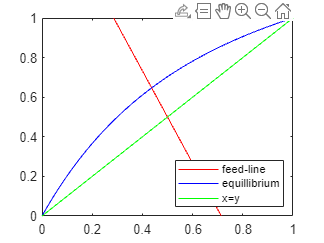

plot(x,feedline,"r") %feedline
hold on
plot(x,eq_curve_linspace,"b") %equillibrium curve
plot(x,x,"g") %x=y line

ylim([0 1])
legend({'feed-line','equillibrium','x=y'} ...
    ,'Location','southeast')

    This Graph Shows feedline without any limitations or intersections. There's several ways to find the intersections. One of which is to substract the curves and make the substraction equal to zero:

substract1= eq_curve(x)' - feedline;
% ' at the end of eq_curve(x) is to make the array horizontal

abs_substract1= abs(substract1);
%to find the lowest difference

x_intersect=find(abs_substract1==min(abs_substract1))

x_intersect = 438

    The intersection box above can be also written as a MATLAB function for easier recalls.

    After the calculation of the intersection, you may plot the final graph:

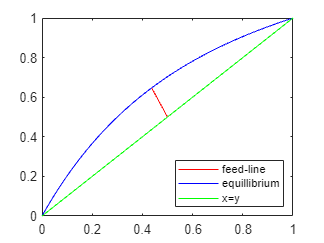

figure();

plot(x( min(500, x_intersect): max(500, x_intersect) ),feedline( min(500, x_intersect): max(500, x_intersect) ),"r") %feedline
hold on
plot(x,eq_curve_linspace,"b") %equillibrium curve
plot(x,x,"g") %x=y line


ylim([0 1])
legend({'feed-line','equillibrium','x=y'} ...
    ,'Location','southeast')

### b) Symbolic Functions:

    Because this approach solve the calculations analytically, it has less errors than previous method.

    First off, we have to define x as a symbolic variable`:`

syms x


    Define feedline and equillibrium curve in linspace function:

%example values
q=0.7;
z=0.5;

feedline_sym=x*q/(q-1)-z/(q-1)

$$feedline\_sym = \frac{5}{3}-\frac{7\,x}{3}$$

eq_curve_sym=subs(str2sym(formula(eq_curve)), ...
    coeffnames(eq_curve), ...
    num2cell(coeffvalues(eq_curve).'))

$$eq\_curve\_sym = \frac{2255922559173967\,x^{5}}{9007199254740992}-\frac{4665659392334037\,x^{4}}{4503599627370496}+\frac{8943902954570845\,x^{3}}{4503599627370496}-\frac{5515107895305007\,x^{2}}{2251799813685248}+\frac{5063763153499859\,x}{2251799813685248}+\frac{8465806512412267}{73786976294838206464}$$

    Where the subs command is for defining the function with given parameters.

    Plot equillibrium curve and feedline:

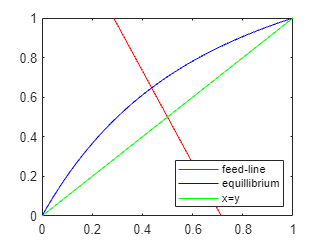

figure();
fplot(feedline_sym,[0,1],"r") %feedline
hold on
fplot(eq_curve_sym,[0,1],"b") %equillibrium curve
plot([0,1],[0,1],"g") %x=y line

ylim([0 1])
xlim([0 1])
legend({'feed-line','equillibrium','x=y'} ...
    ,'Location','southeast')

    This Graph Shows feedline without any limitations or intersections. To find the intersection, symbolic commands will be used:

x_intersect_sym= vpasolve(feedline_sym==eq_curve_sym,[0,1])

$$x\_intersect\_sym = 0.4369857308021430607069103882749$$

y_intersect_sym= subs(eq_curve_sym,x_intersect_sym)

$$y\_intersect\_sym = 0.64703329479499952501720909402524$$

    Note that in this approach, y_intersection must be calculated.

    After the calculation of the intersection coordinates, you may plot the final graph:

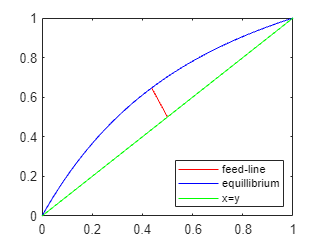

figure();

plot([z x_intersect_sym] ,[z y_intersect_sym],"r") %feedline
hold on
fplot(eq_curve_sym,[0,1],"b") %equillibrium curve
plot([0,1],[0,1],"g") %x=y line

ylim([0 1])
xlim([0 1])
legend({'feed-line','equillibrium','x=y'} ...
    ,'Location','southeast')